Alen Mehmedbegovic         301476201 

Question 1

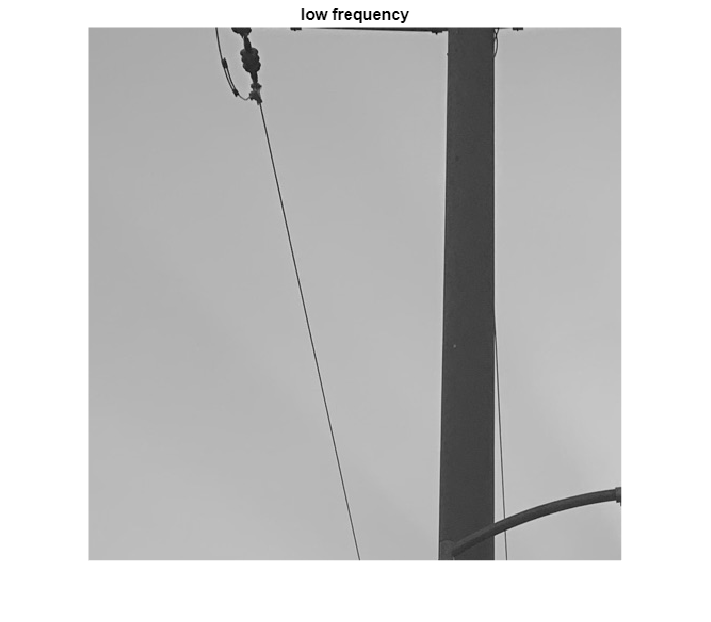

HP = imread('toysflash.png');
HP = HP(1:500, 200:699, :);   % Crop
HP = im2double(HP);         
HP = rgb2gray(HP);        % Convert to greyscale 
imwrite(HP, "HP.png");

LP = imread("BeautifulCroatia.jpeg");
LP = LP(1:500, 200:699, :);   % Crop
LP = im2double(LP);         
LP = rgb2gray(LP);        % Convert to greyscale 
imwrite(LP, "LP.png");

imshow(LP);
title('low frequency');

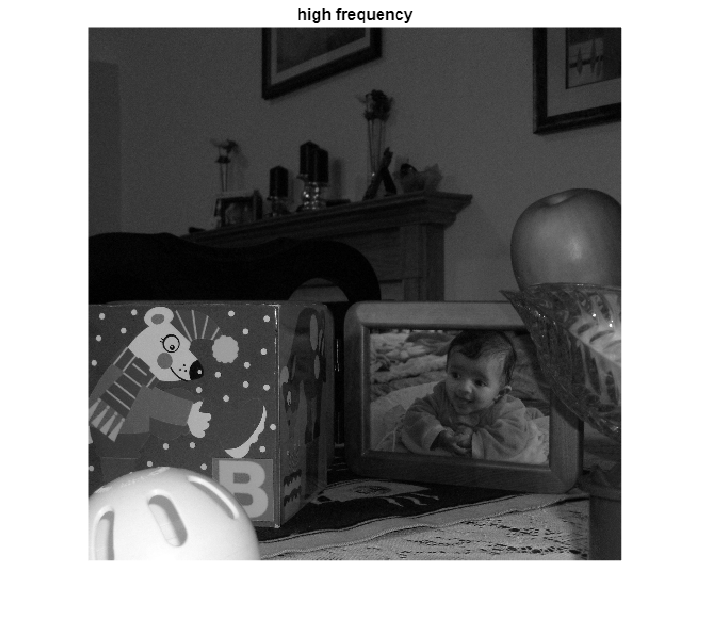

imshow(HP);
title('high frequency')

Question 2

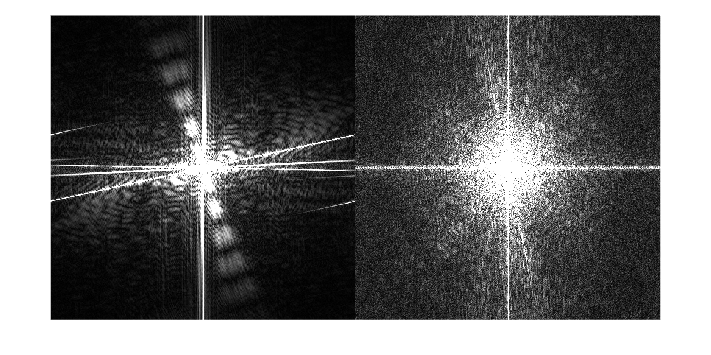

LP_FT = fft2(LP);
HP_FT = fft2(HP);
imshow([fftshift(abs(LP_FT)) fftshift(abs(HP_FT))]/ 50)

% As we can see, low frequency image is more concentrated in center and
% high frequency is more spread out across image. As expected 

Question 3

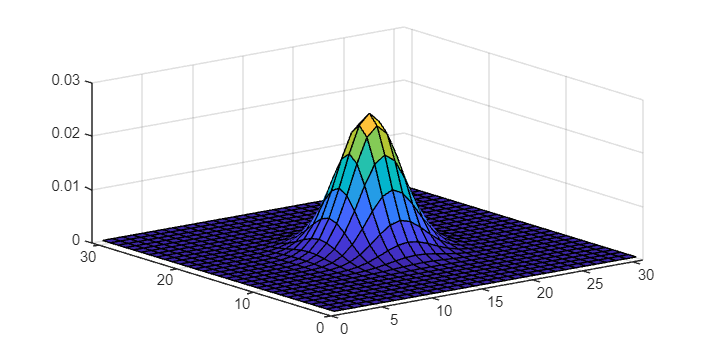

% Sobel kernel
sob = [-1 0 1; -2 0 2; -1 0 1];

% Gaussian kernel
gauss = fspecial('gaussian', 31, 2.5);
% gaussian fliter, with 31x31 dimensions and SD 2.5
% we choose odd numbers for the dimensions as the size of pixels 
% are discrete so if we want to center one kernel on top of a pixel 
% it needs to be odd
saveas(surf(gauss), "gaus-surf.png"); 

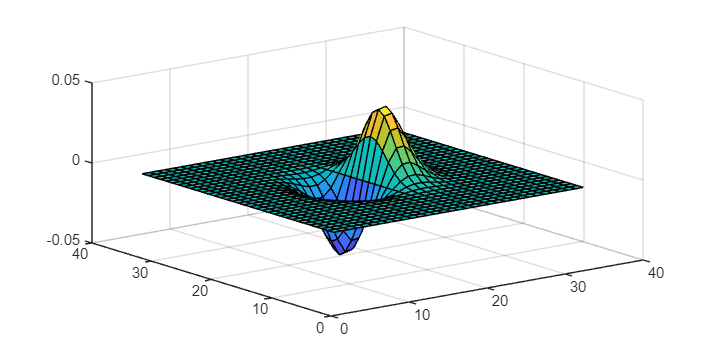


% DoG kernel
DoG = conv2(gauss, sob);
saveas(surf(DoG), "dog-surf.png"); 


% Apply gaussian filter to LP and HP 
LPgaus = imfilter(LP,gauss);
HPgaus = imfilter(HP,gauss);
% Compute frequency representations of them
LPgaus_FT = fftshift(abs(fft2(LPgaus)));
HPgaus_FT = fftshift(abs(fft2(HPgaus))); 
imwrite(LPgaus, "LP-flit.png");
imwrite(HPgaus, "HP-flit.png");
imwrite(LPgaus_FT, "LP-flit-freq.png");
imwrite(HPgaus_FT, "HP-flit-freq.png");

% Compute fourier transform of DoG kernel 
DoGFT = fft2(DoG, 500, 500);
% Multiplication in spatial = convolution in frequency 
% Convolution theorem states that the fourier transform of a convolution *
% between two functions is the product of their fourier transforms 
% F(g*h) = F(g)F(h)  <==> F^-1(g*h) = F^-1(g)F^-1(h)
LPfiltfreq = DoGFT.*LP;
imwrite(fftshift(abs(LPfiltfreq)), "LP-dogfilt-freq.png")

HPfiltfreq = DoGFT.*HP;
imwrite(fftshift(abs(HPfiltfreq)), "HP-dogfilt-freq.png")

LPfiltspace = ifft2(LPfiltfreq);
imwrite(abs(LPfiltspace), "LP-dogfilt.png")

HPfiltspace = ifft2(HPfiltfreq);
imwrite(abs(HPfiltspace), "HP-dogfilt.png")

Question 4

Question 5